%% Initialization
% This is to compute MC on the real robot with 3 mm blade leg, both
% actuated
% key difference is that the bin size is 100
clear;
%bins = 100;
cd C:\Users\vjc28\OneDrive\Documents\dissertation\robot_properties_solo-master\Models
load('simdata_201223.mat');
realfiles_b2_3.name = 'Real_ModelOutput_2blade_3mm';
R_motor = 0.452 %ohms from TMotor datasheet

R_motor = 0.4520


%% 1. Step: Extract min/max values for each column that will be used
dispRb2_3_min  = 0; dispRb2_3_max = 0;
accnRb2_3_min = 0; accnRb2_3_max = 0;
velRb2_3_min  = 0; velRb2_3_max = 0;
actRb2_3_min  = 0; actRb2_3_max = 1.0;
%s_min  = 0; s_max = 0;

real_string = '';


%for file_index = 1:length(files)
%load(solofiles.name,'SimData');

% position      = SimData(:,2);
% velocity      = SimData(:,3);
% accelaration  = SimData(:,4);
% action        = SimData(:,10);
% muscle_sensor = SimData(:,5);


realfiles_b2_3.Hposition      = plot2blade3mm(:,1); %joint angle of hip
realfiles_b2_3.Kposition      = plot2blade3mm(:,7); %joint angle of knee
realfiles_b2_3.Hvelocity      = plot2blade3mm(:,2)/9; %angular velocity of hip adjusted for gear ratio
realfiles_b2_3.kvelocity      = plot2blade3mm(:,8)/9; %angulat velocity of knee adjusted for gear ratio
realfiles_b2_3.Ztip           = 0.16*(cos(realfiles_b2_3.Hposition/9)+cos((realfiles_b2_3.Hposition+realfiles_b2_3.Kposition)/9)) % using forward kinematics find the Z axis movement of tip. l1 = l2 = 160mm, angle is 1/9 due to gearing ratio

realfiles_b2_3 = struct with fields:
           name: 'Real_ModelOutput_2blade_3mm'
      Hposition: [30001×1 double]
      Kposition: [30001×1 double]
      Hvelocity: [30001×1 double]
      kvelocity: [30001×1 double]
           Ztip: [30001×1 double]
           Xtip: [30001×1 double]
        Haction: [30001×1 double]
        Kaction: [30001×1 double]
       Hcurrent: [30001×1 double]
       Kcurrent: [30001×1 double]
          Force: [30001×1 double]
      MechPower: [30001×1 double]
      ForceCalc: [30001×1 double]
         d_Ztip: [30001×1 int64]
    d_kvelocity: [30001×1 int64]
      d_Kaction: [30001×1 int64]
              w: [30001×1 double]
            mcw: 6.7835
            mcd: [30000×1 double]
     smooth_mcd: [30000×1 double]
    smooth2_mcd: [30000×1 double]


realfiles_b2_3.Xtip           = 0.16*(sin(realfiles_b2_3.Hposition/9)+sin((realfiles_b2_3.Hposition+realfiles_b2_3.Kposition)/9))

realfiles_b2_3 = struct with fields:
           name: 'Real_ModelOutput_2blade_3mm'
      Hposition: [30001×1 double]
      Kposition: [30001×1 double]
      Hvelocity: [30001×1 double]
      kvelocity: [30001×1 double]
           Ztip: [30001×1 double]
           Xtip: [30001×1 double]
        Haction: [30001×1 double]
        Kaction: [30001×1 double]
       Hcurrent: [30001×1 double]
       Kcurrent: [30001×1 double]
          Force: [30001×1 double]
      MechPower: [30001×1 double]
      ForceCalc: [30001×1 double]
         d_Ztip: [30001×1 int64]
    d_kvelocity: [30001×1 int64]
      d_Kaction: [30001×1 int64]
              w: [30001×1 double]
            mcw: 6.7835
            mcd: [30000×1 double]
     smooth_mcd: [30000×1 double]
    smooth2_mcd: [30000×1 double]


%realfiles.Hacceleration   = accn_solo.Data;
realfiles_b2_3.Haction         = plot2blade3mm(:,3);% hip output of PD controller - ref current to motor
realfiles_b2_3.Kaction        = plot2blade3mm (:,9) % knee output

realfiles_b2_3 = struct with fields:
           name: 'Real_ModelOutput_2blade_3mm'
      Hposition: [30001×1 double]
      Kposition: [30001×1 double]
      Hvelocity: [30001×1 double]
      kvelocity: [30001×1 double]
           Ztip: [30001×1 double]
           Xtip: [30001×1 double]
        Haction: [30001×1 double]
        Kaction: [30001×1 double]
       Hcurrent: [30001×1 double]
       Kcurrent: [30001×1 double]
          Force: [30001×1 double]
      MechPower: [30001×1 double]
      ForceCalc: [30001×1 double]
         d_Ztip: [30001×1 int64]
    d_kvelocity: [30001×1 int64]
      d_Kaction: [30001×1 int64]
              w: [30001×1 double]
            mcw: 6.7835
            mcd: [30000×1 double]
     smooth_mcd: [30000×1 double]
    smooth2_mcd: [30000×1 double]


%solofiles.msensor        = muscle_sensor;
realfiles_b2_3.Hcurrent       = plot2blade3mm (:,4); % Hip actual current 
realfiles_b2_3.Kcurrent       = plot2blade3mm (:,10) % Knee actual current 

realfiles_b2_3 = struct with fields:
           name: 'Real_ModelOutput_2blade_3mm'
      Hposition: [30001×1 double]
      Kposition: [30001×1 double]
      Hvelocity: [30001×1 double]
      kvelocity: [30001×1 double]
           Ztip: [30001×1 double]
           Xtip: [30001×1 double]
        Haction: [30001×1 double]
        Kaction: [30001×1 double]
       Hcurrent: [30001×1 double]
       Kcurrent: [30001×1 double]
          Force: [30001×1 double]
      MechPower: [30001×1 double]
      ForceCalc: [30001×1 double]
         d_Ztip: [30001×1 int64]
    d_kvelocity: [30001×1 int64]
      d_Kaction: [30001×1 int64]
              w: [30001×1 double]
            mcw: 6.7835
            mcd: [30000×1 double]
     smooth_mcd: [30000×1 double]
    smooth2_mcd: [30000×1 double]


realfiles_b2_3.Force          = plot2blade3mm (:,6) % load cell input (N)

realfiles_b2_3 = struct with fields:
           name: 'Real_ModelOutput_2blade_3mm'
      Hposition: [30001×1 double]
      Kposition: [30001×1 double]
      Hvelocity: [30001×1 double]
      kvelocity: [30001×1 double]
           Ztip: [30001×1 double]
           Xtip: [30001×1 double]
        Haction: [30001×1 double]
        Kaction: [30001×1 double]
       Hcurrent: [30001×1 double]
       Kcurrent: [30001×1 double]
          Force: [30001×1 double]
      MechPower: [30001×1 double]
      ForceCalc: [30001×1 double]
         d_Ztip: [30001×1 int64]
    d_kvelocity: [30001×1 int64]
      d_Kaction: [30001×1 int64]
              w: [30001×1 double]
            mcw: 6.7835
            mcd: [30000×1 double]
     smooth_mcd: [30000×1 double]
    smooth2_mcd: [30000×1 double]


realfiles_b2_3.MechPower      = abs(plot2blade3mm (:,4).*plot2blade3mm(:,2)*0.025)+ abs(plot2blade3mm (:,10).*plot2blade3mm(:,8)*0.025)

realfiles_b2_3 = struct with fields:
           name: 'Real_ModelOutput_2blade_3mm'
      Hposition: [30001×1 double]
      Kposition: [30001×1 double]
      Hvelocity: [30001×1 double]
      kvelocity: [30001×1 double]
           Ztip: [30001×1 double]
           Xtip: [30001×1 double]
        Haction: [30001×1 double]
        Kaction: [30001×1 double]
       Hcurrent: [30001×1 double]
       Kcurrent: [30001×1 double]
          Force: [30001×1 double]
      MechPower: [30001×1 double]
      ForceCalc: [30001×1 double]
         d_Ztip: [30001×1 int64]
    d_kvelocity: [30001×1 int64]
      d_Kaction: [30001×1 int64]
              w: [30001×1 double]
            mcw: 6.7835
            mcd: [30000×1 double]
     smooth_mcd: [30000×1 double]
    smooth2_mcd: [30000×1 double]


realfiles_b2_3.ForceCalc      = (plot2blade3mm (:,6)-0.3)*7; %actual force calculation
realfiles_b2_3.MotorLoss      = (realfiles_b2_3.Hcurrent.^2+realfiles_b2_3.Kcurrent.^2)*R_motor

realfiles_b2_3 = struct with fields:
           name: 'Real_ModelOutput_2blade_3mm'
      Hposition: [30001×1 double]
      Kposition: [30001×1 double]
      Hvelocity: [30001×1 double]
      kvelocity: [30001×1 double]
           Ztip: [30001×1 double]
           Xtip: [30001×1 double]
        Haction: [30001×1 double]
        Kaction: [30001×1 double]
       Hcurrent: [30001×1 double]
       Kcurrent: [30001×1 double]
          Force: [30001×1 double]
      MechPower: [30001×1 double]
      ForceCalc: [30001×1 double]
         d_Ztip: [30001×1 int64]
    d_kvelocity: [30001×1 int64]
      d_Kaction: [30001×1 int64]
              w: [30001×1 double]
            mcw: 6.7835
            mcd: [30000×1 double]
     smooth_mcd: [30000×1 double]
    smooth2_mcd: [30000×1 double]
      MotorLoss: [30001×1 double]


dispRb2_3_min = min(realfiles_b2_3.Ztip);   %minimum position of Ztip
dispRb2_3_max = max(realfiles_b2_3.Ztip);

velRb2_3_min = min(realfiles_b2_3.kvelocity);
velRb2_3_max = max(realfiles_b2_3.kvelocity);

% s_min = min(muscle_sensor);
% s_max = max(muscle_sensor);

% accnR_min = min(accn_solo.Data);
% accnR_max = max(accn_solo.Data);

actRb2_3_min = min(realfiles_b2_3.Kaction);
actRb2_3_max = max(realfiles_b2_3.Kaction);

%end

real_string = [real_string 'Domains\n' ...
    sprintf('  Position:        %f, %f\n', dispRb2_3_min, dispRb2_3_max) ...
    sprintf('  Velocity:        %f, %f\n', velRb2_3_min, velRb2_3_max) ...
    sprintf('  Actuator signal: %f, %f\n', actRb2_3_min, actRb2_3_max)]

real_string =     'Domains\n  Position:        0.258917, 0.319987
       Velocity:        -2.649915, 3.444760
       Actuator signal: -1.105847, 2.202828
     '



%Discretise Test
bins=100;
fprintf('Bins = %d\n', bins)

Bins = 100


w_bins = bins;
a_bins = bins;
s_bins = bins;
realfiles_b2_3.d_Ztip     = discretiseMatrix(realfiles_b2_3.Ztip, dispRb2_3_min, dispRb2_3_max, w_bins);
realfiles_b2_3.d_kvelocity     = discretiseMatrix(realfiles_b2_3.kvelocity, velRb2_3_min, velRb2_3_max, w_bins);
%realfiles.d_accelaration = discretiseMatrix(realfiles.acceleration, accnR_min, accnR_max, w_bins);
realfiles_b2_3.d_Kaction            = discretiseMatrix(realfiles_b2_3.Kaction, actRb2_3_min, actRb2_3_max, a_bins);


% create univariate variable
realfiles_b2_3.w              = combineAndRelabelBinnedMatrix([realfiles_b2_3.d_Ztip, realfiles_b2_3.d_kvelocity]);
    

%measure MC 

fprintf('Working on file %s\n', realfiles_b2_3.name)

Working on file Real_ModelOutput_2blade_3mm



real_b2w2_3 = realfiles_b2_3.w(2:end,:);
real_b2w1_3 = realfiles_b2_3.w(1:end-1,:);

real_b2a1_3 = realfiles_b2_3.d_Kaction(1:end-1,:);
%s1 = files.s(1:end-1,:);
% for t = 1:length(w1)
%     w2index = w2(t)
%     w1index = w1(t)
%     a1index = a1(t)
% end
%zeros(max(solo_w2),max(solo_w1),max(solo_a1))


realfiles_b2_3.mcw  = MC_W1(real_b2w2_3, real_b2w1_3, real_b2a1_3);
fprintf('MC_W %f\n', realfiles_b2_3.mcw);

MC_W 6.783464



mcwd2b_3 = MC_W1_dynamic(real_b2w2_3, real_b2w1_3, real_b2a1_3);
realfiles_b2_3.mcd  = mcwd2b_3;
fprintf('check %f\n', realfiles_b2_3.mcw - mean(mcwd2b_3));

check 0.000001


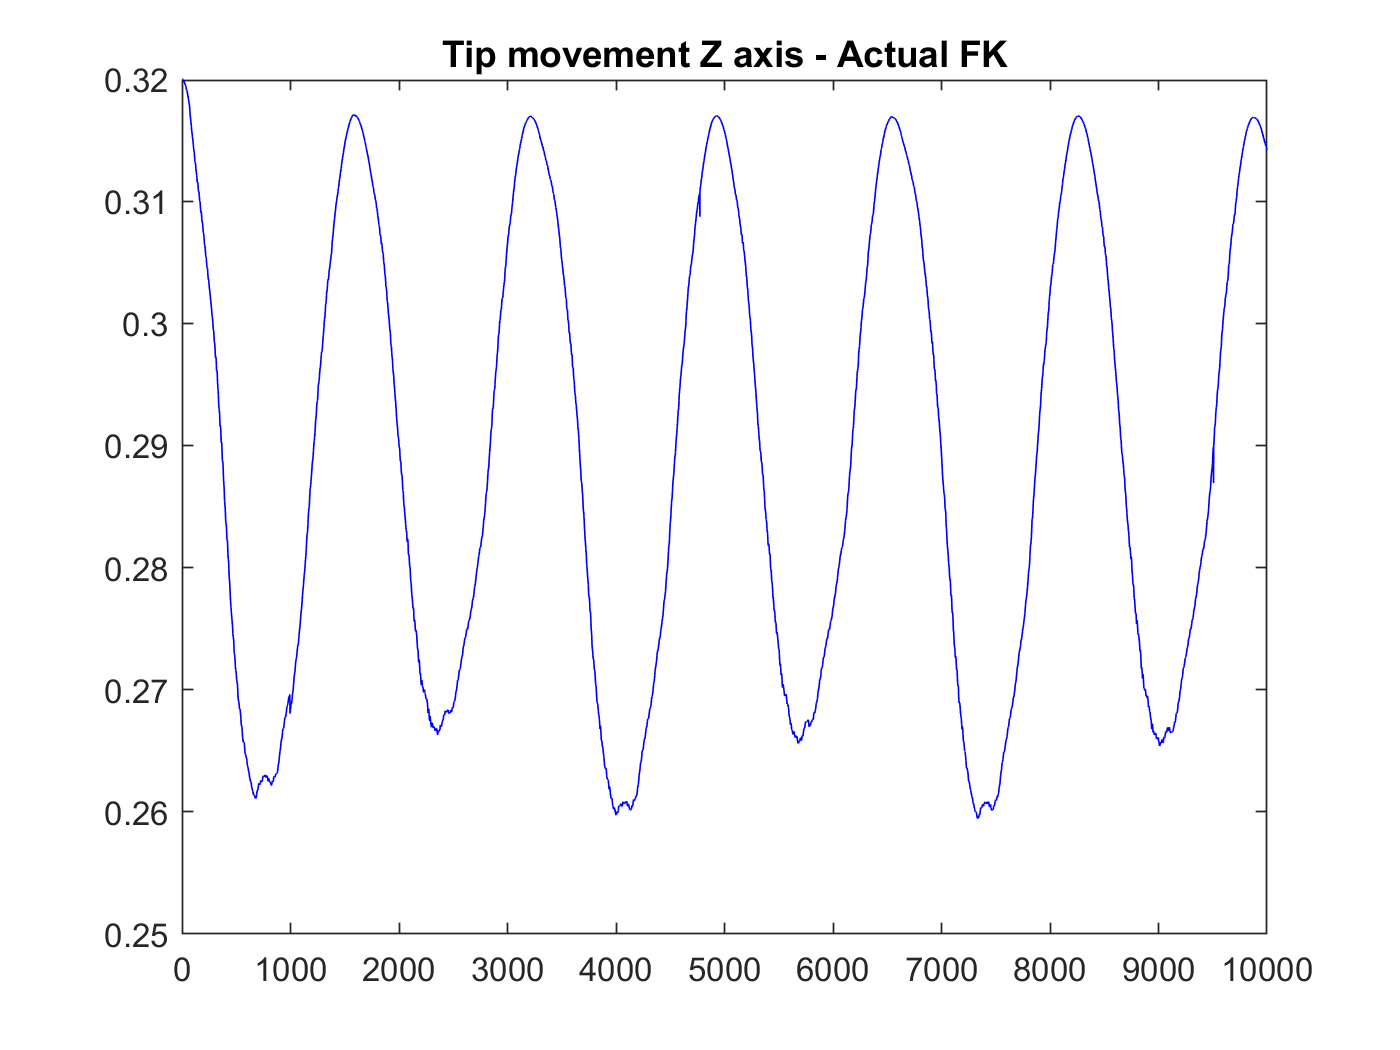

plot(realfiles_b2_3.Ztip,'bl')
title('Tip movement Z axis - Actual FK')
xlim([0 10000])
hold off;

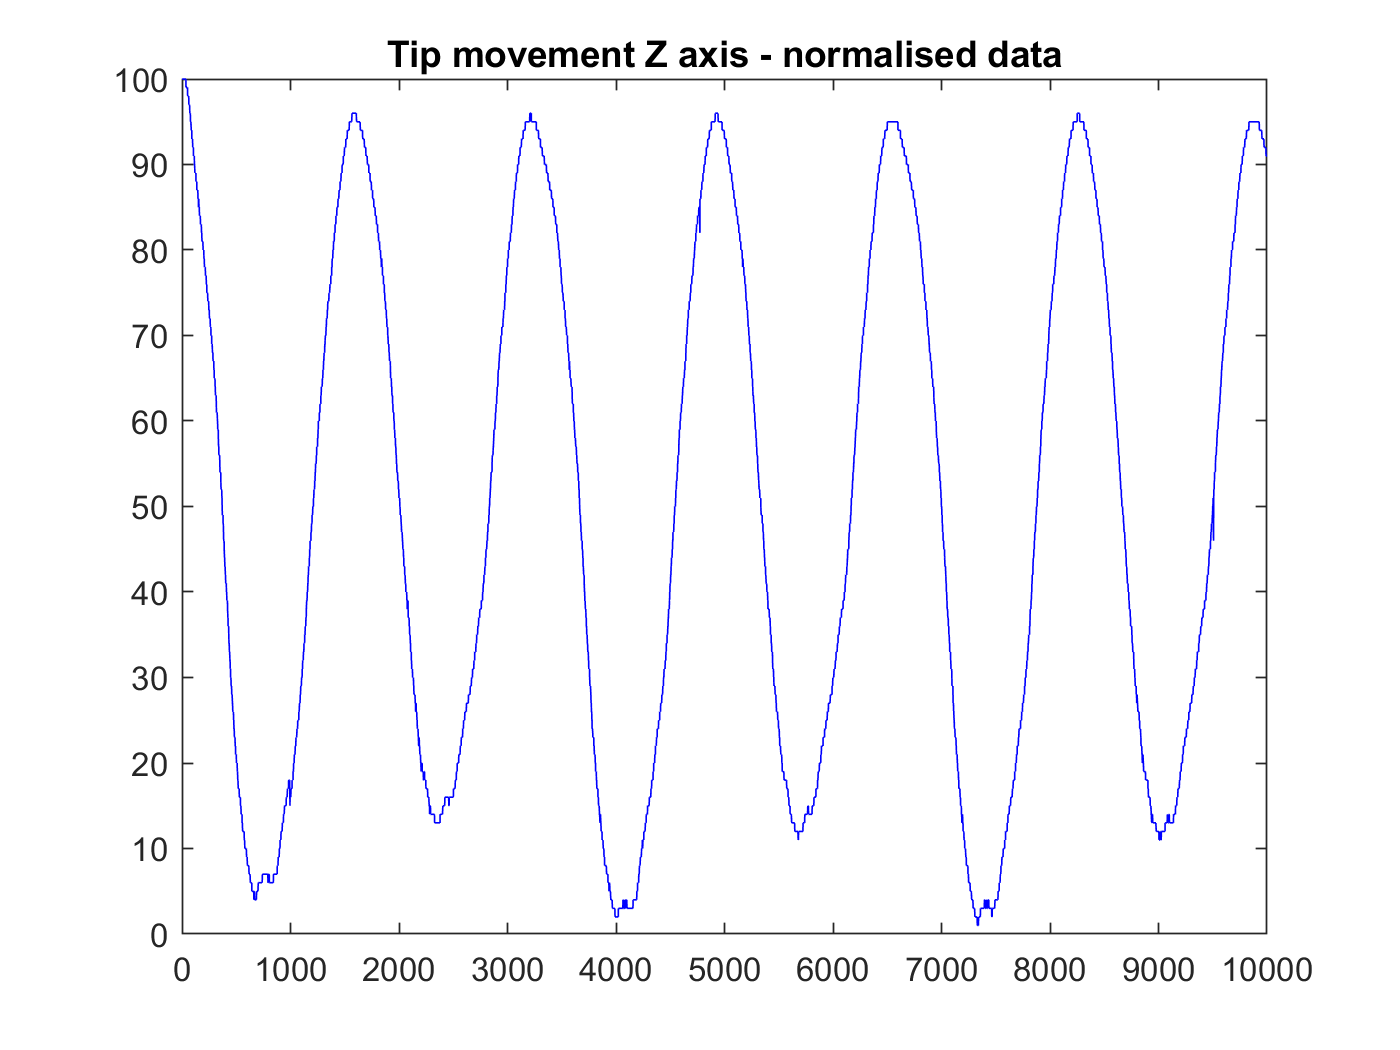

plot(realfiles_b2_3.d_Ztip,'b')
title ('Tip movement Z axis - normalised data')
xlim([0 10000])


hold off;

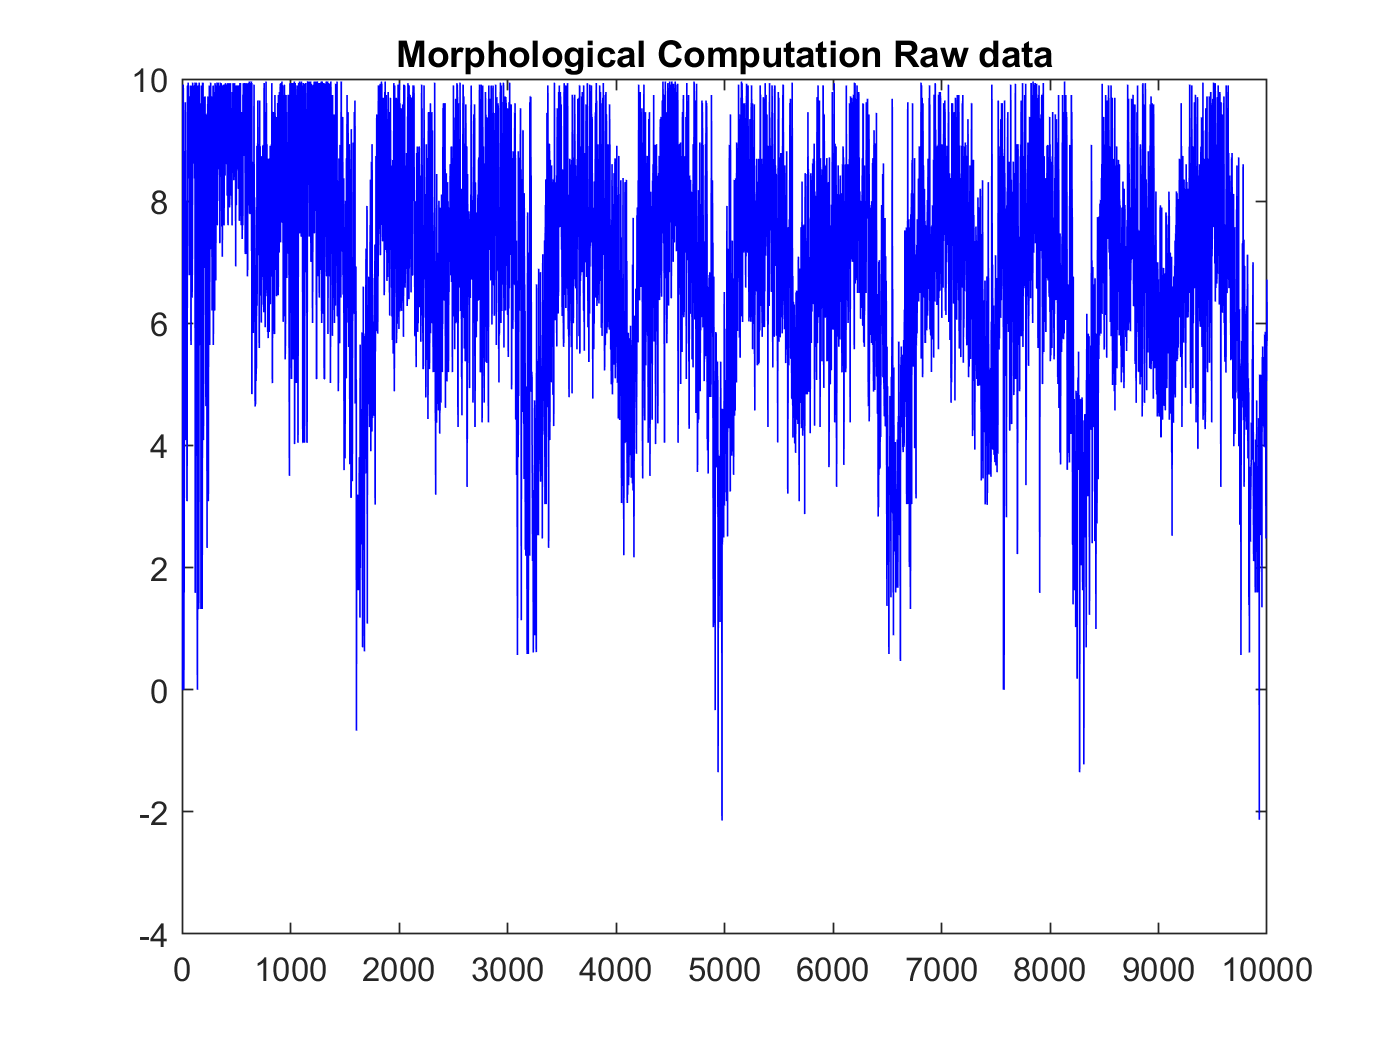

plot(realfiles_b2_3.mcd,'b')
title('Morphological Computation Raw data')
xlim([0 10000]);

%xticklabels([''])
%ylim([-2.0 12.0])

realfiles_b2_3.smooth_mcd = smoothdata(realfiles_b2_3.mcd);
hold off

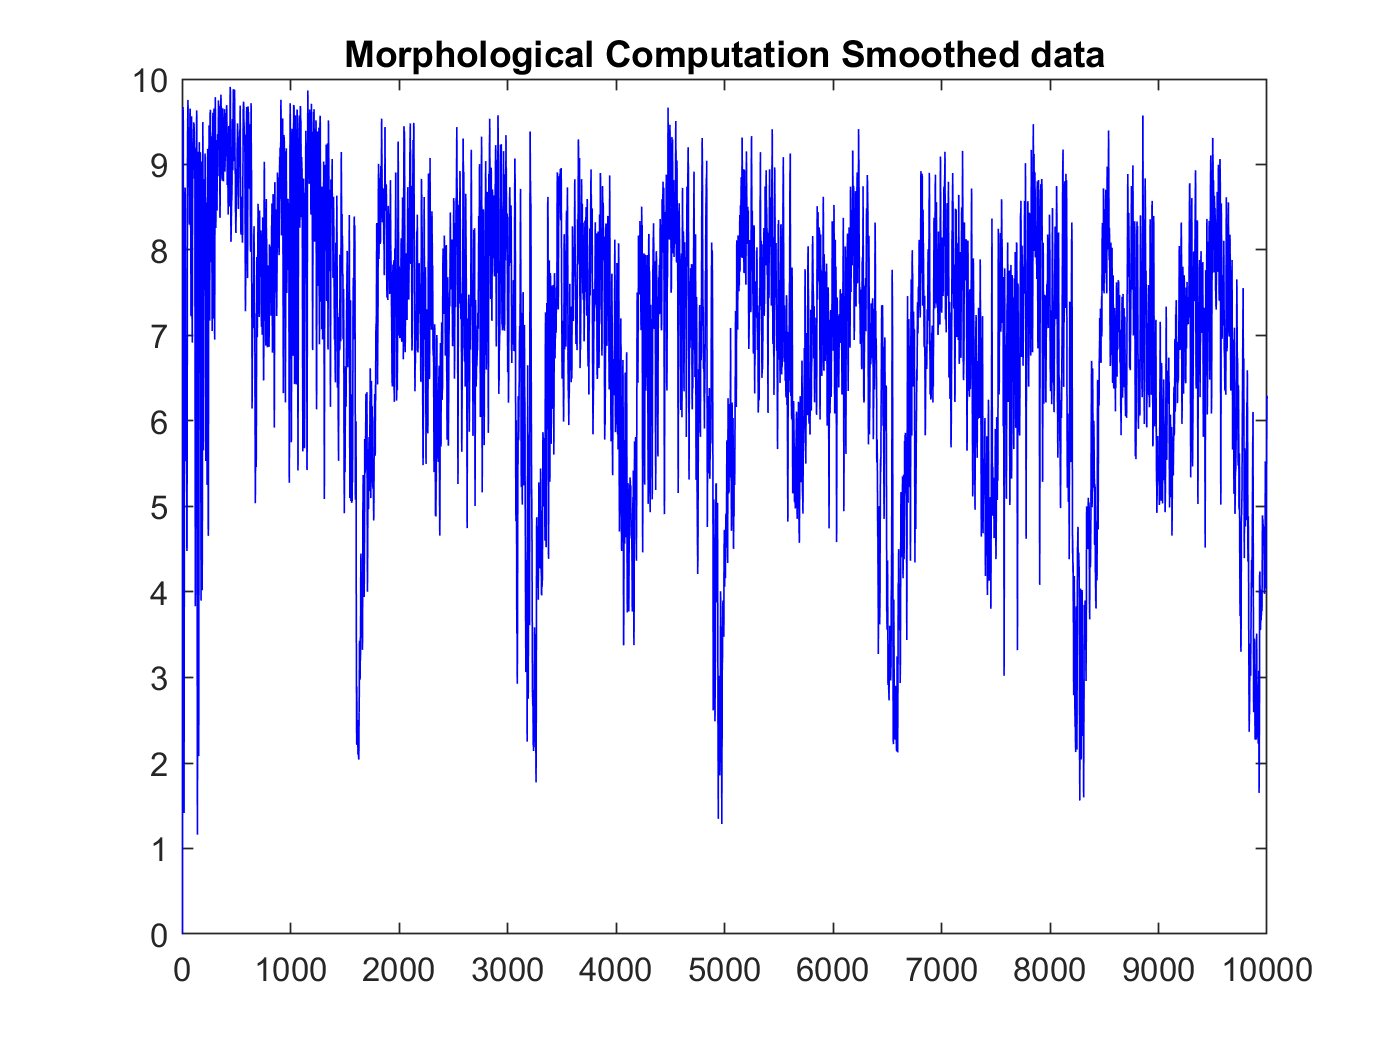

plot(realfiles_b2_3.smooth_mcd,'b')
title('Morphological Computation Smoothed data')
xlim([0 10000]);

realfiles_b2_3.smooth_mcd = smoothdata(realfiles_b2_3.mcd);
hold off

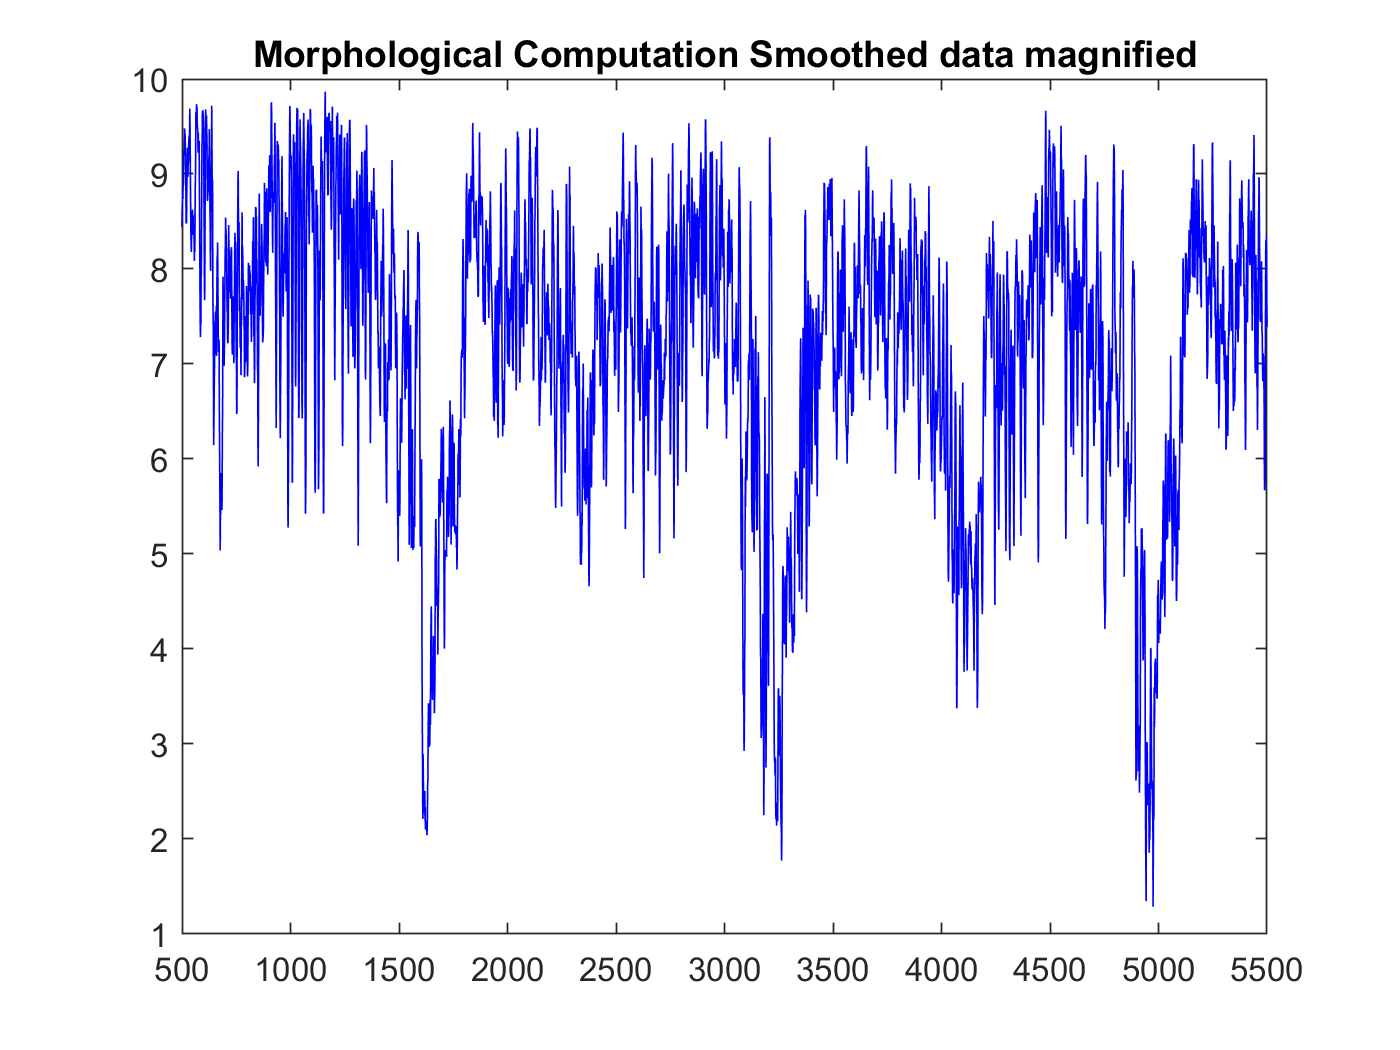

plot(realfiles_b2_3.smooth_mcd,'b')
title('Morphological Computation Smoothed data magnified')
xlim([500 5500]);

realfiles_b2_3.smooth2_mcd = smoothdata(realfiles_b2_3.smooth_mcd);
hold off

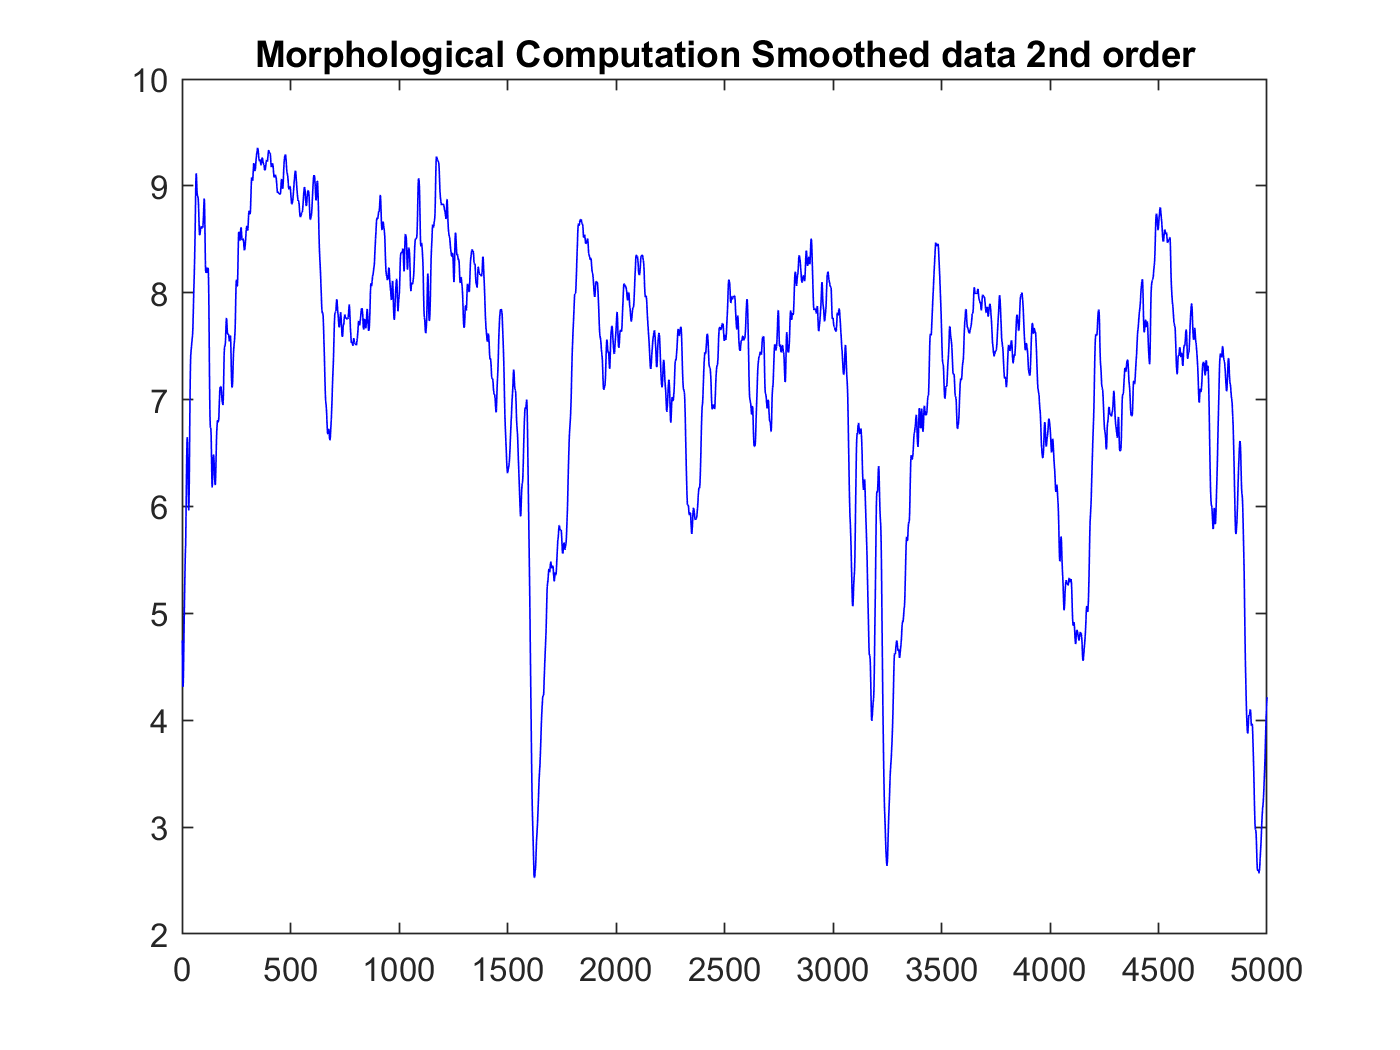

plot(realfiles_b2_3.smooth2_mcd,'b')
title('Morphological Computation Smoothed data 2nd order')
xlim([0 5000]);

hold off;

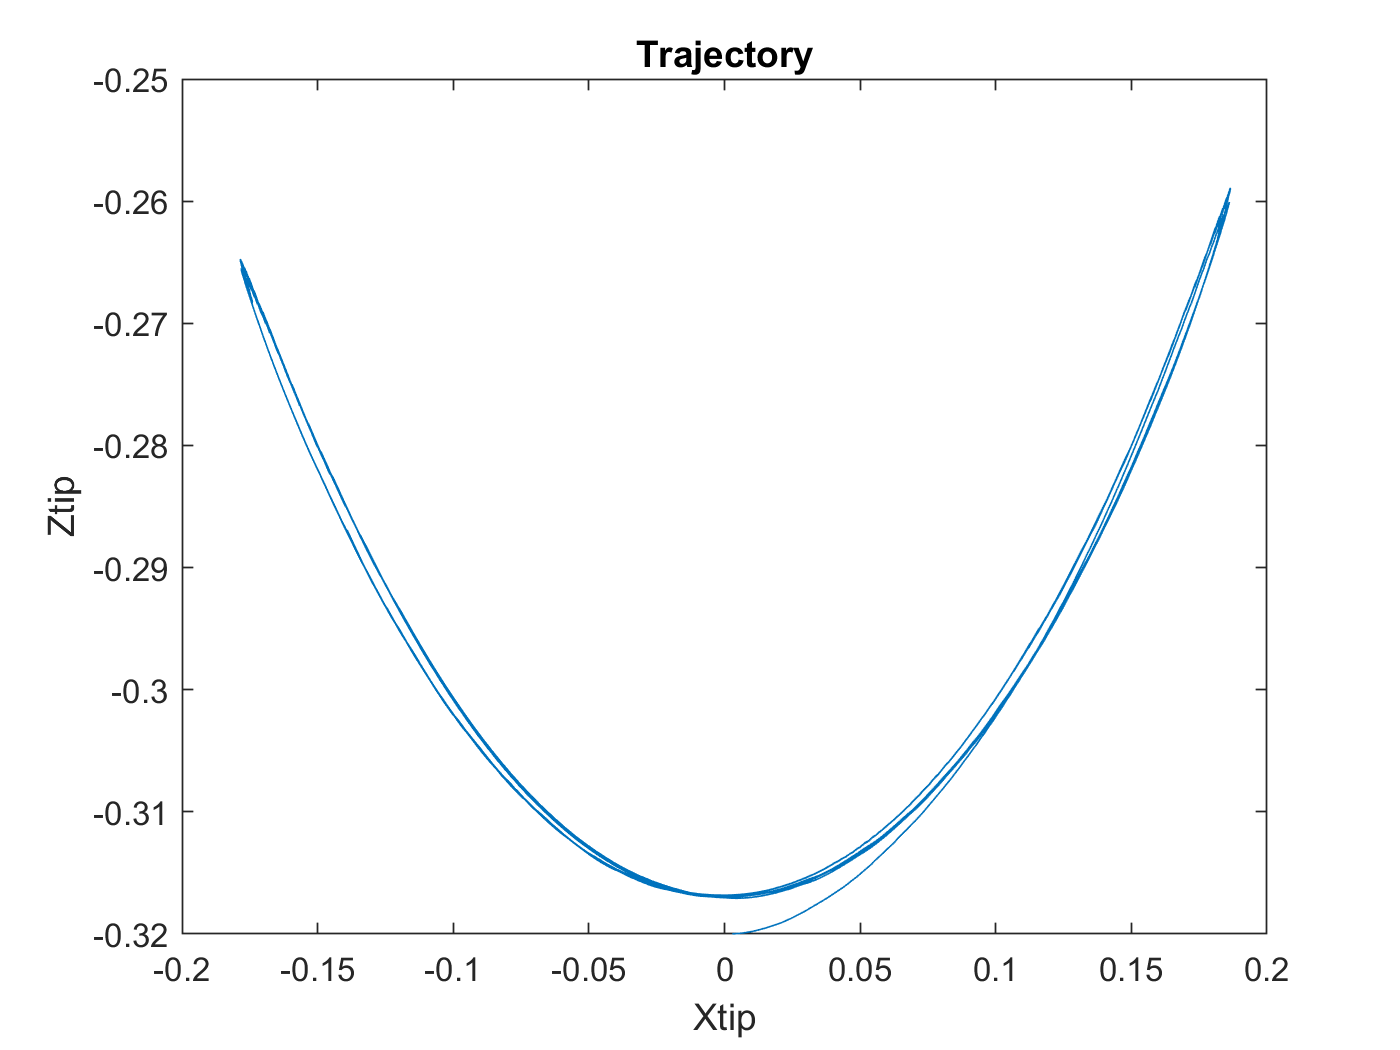

plot(realfiles_b2_3.Xtip,-realfiles_b2_3.Ztip)
title('Trajectory')
ylabel('Ztip')
xlabel('Xtip')